# Requirements writing exercise

This exercise introduces basic concepts about requirements writing. 

**The main objective is to write scooter motor requirements from customer requirements given in this document.**

The company MU Scooters Inc. is looking for a supplier of electric motors. You (student) are part of a company that manufactures electric motors. 

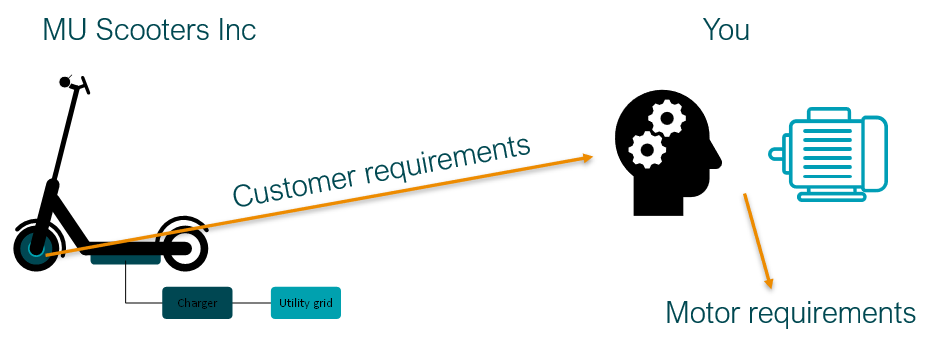

The exercise will consist of the following tasks:

- Read carefully customer requirements given in the following sections. *Remember that these requirements may be given in an informal and unstructured way. The objective is to convert what the customer asks for into formal requirements for the motor.*

- Start writing two motor requirements. 

- Create a requirement set and requirements in MATLAB Requirement Editor.

- Complete the attributes present in the Requirement Editor.

- Complete the whole requirement set taking into account the information given by the customer.

Take into account the guidelines given in class theory. **The exercise will be evaluated following those guidelines.**

The deliverable will contain a MALTAB requirements set file (slreqx) and a word file imported directly from the editor.

## 1. Introduction

### 1.1 Purpose

This document was prepared by MU Scooters Inc. It presents the requirements for a electric scooter motor. Its purpose is to help suppliers to specify motor requirements.

### 1.2 Background and context

MU Scooters Inc. is designing and manufacturing a electric scooter for urban mobility. The architecture of the scooter is shown in the following figure.

It will be a two-wheeled lightweight aluminium frame scooter with 25 km/h maximum speed. A maximum weight of 4 kg is expected (including all the parts).

Battery (24 V) and electronics will go underneath the structure. An in-wheel motor with a 10 inch inflatable wheel will be used.

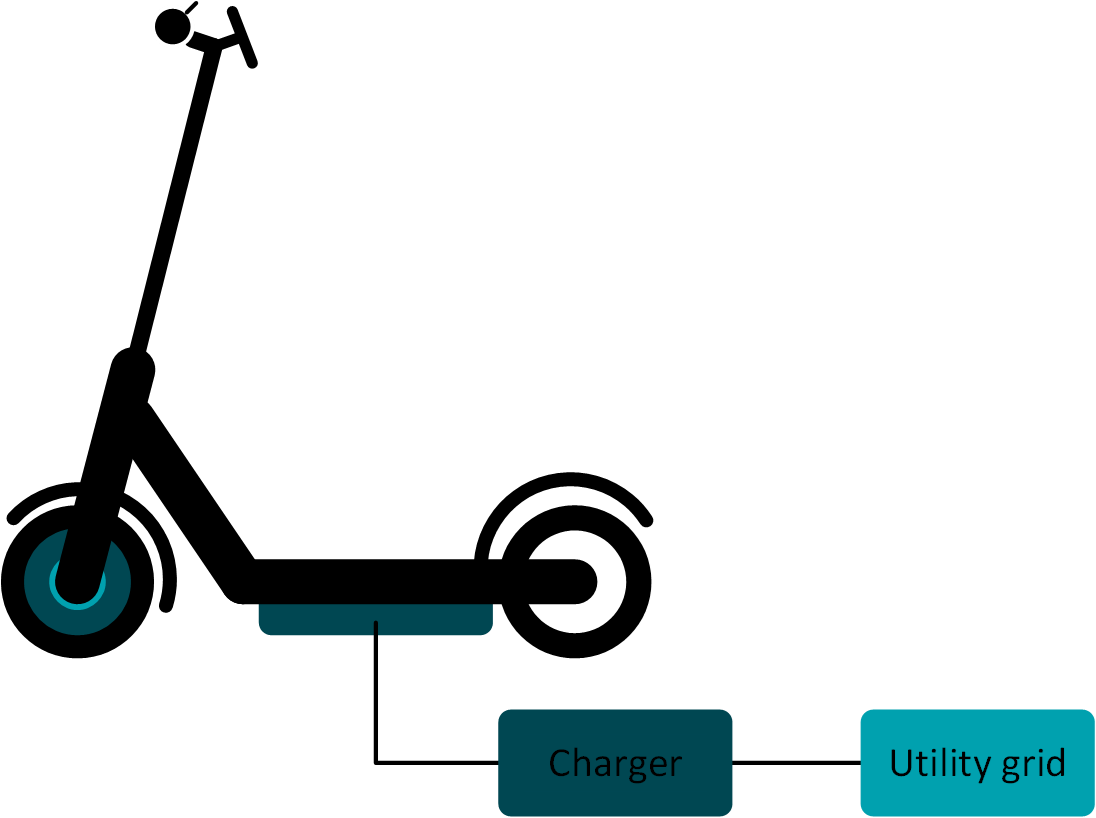

The scooter will be sold together with a battery charger. In terms of connectivity, the scooter will have a 4.7" screen with bluetooth connectivity. The screen will be used to show battery state-of-charge information and gps information handling. 

## 2. Motor characteristics

In order to size the motor, Mu Scooters Inc. has simulated several routes. The dynamic behaviour of the routes was stored in .mat files.

### Load route dynamic info

There are three example routes:

routeSelect = "Route 3";
switch routeSelect
    case "Route 1"
        load dynamicsGalarreta2Anoeta
    case "Route 2"
        load dynamicsGros2Ulia
    case "Route 3"
        load dynamicsGros2Ibaeta
    otherwise
        load dynamicsGalarreta2Anoeta
end

### Plot speed and torque

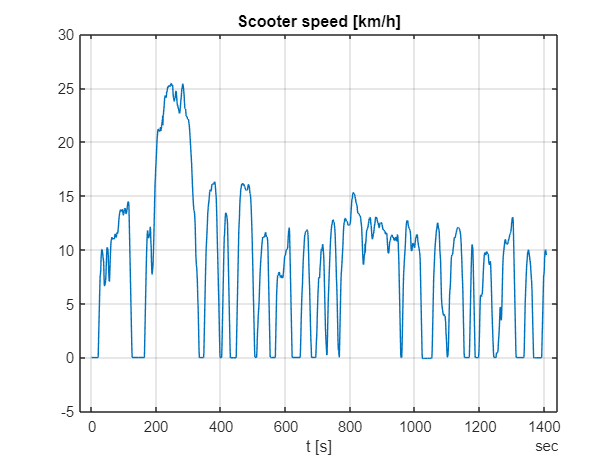

% Speed
plot(logsout{3}.Values.vScooter__km_h_.Time,logsout{3}.Values.vScooter__km_h_.Data)
title('Scooter speed [km/h]')
xlabel('t [s]')
grid

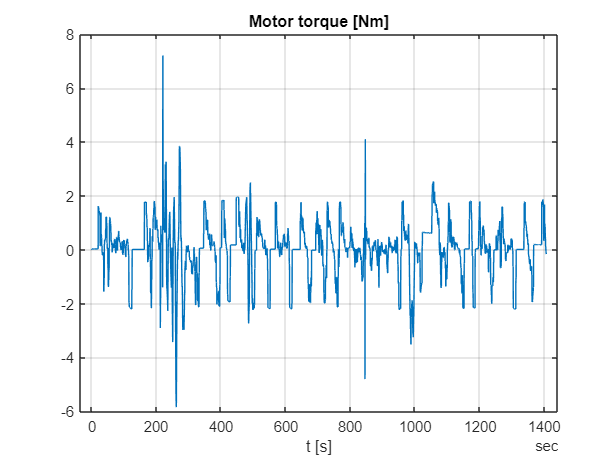


% Torque
plot(logsout{2}.Values.TemRef.Time,logsout{2}.Values.TemRef.Data)
title('Motor torque [Nm]')
xlabel('t [s]')
grid

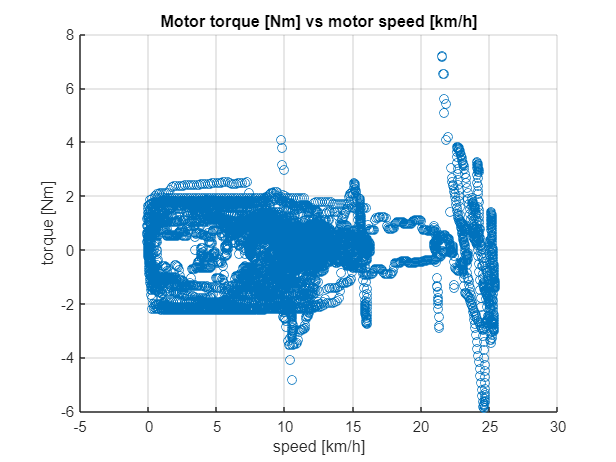

% Torque speed curve
%% Torque speed curve
scatter(logsout{3}.Values.vScooter__km_h_.Data,logsout{2}.Values.TemRef.Data)
title('Motor torque [Nm] vs motor speed [km/h]')
xlabel('speed [km/h]')
ylabel('torque [Nm]')
grid

### Equivalent, maximum and minimum torque 

The equivalent rms, maximum, minimum torque and maximum speed for the route are shown below.

Equivalent rms torque:

Trms = rms(logsout{2}.Values.TemRef.Data)

Trms = 1.0335

Maximum torque:

Tmax = max(logsout{2}.Values.TemRef.Data)

Tmax = 7.2036

Minimum torque:

Tmin = min(logsout{2}.Values.TemRef.Data)

Tmin = -5.8428

Maximum speed:

vMax = max(logsout{3}.Values.vScooter__km_h_.Data)

vMax = 25.4384

*Copyright 2022 Mondragon Goi Eskola Politeknikoa.*

[*www.mondragon.edu/msie*](http://www.mondragon.edu/msie)

*jdelolmo@mondragon.edu*